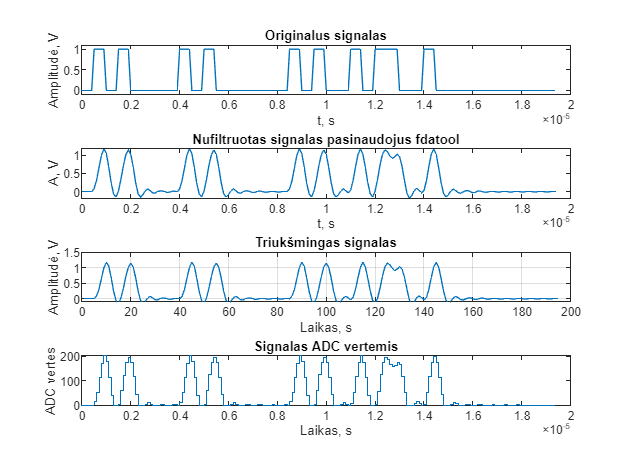

fdiskret = 10E6;
tdiskret = 1/fdiskret;
A = 1;
maxA = 1.5;
minA = 0;
ADCbits = 8;

idealOne = [ones(1, round(0.5E-6/tdiskret)), zeros(1, round(0.5E-6/tdiskret))];
idealZero = [zeros(1, round(0.5E-6/tdiskret)), ones(1, round(0.5E-6/tdiskret))];


idealPreambule = [ones(1, round(0.5E-6/tdiskret)), zeros(1, round(0.5E-6/tdiskret)), ones(1, round(0.5E-6/tdiskret)), zeros(1, round(2E-6/tdiskret)), ones(1, round(0.5E-6/tdiskret)), zeros(1, round(0.5E-6/tdiskret)), ones(1, round(0.5E-6/tdiskret))];
idealFullSignal = [zeros(1, 5), idealPreambule, zeros(1, round(3E-6/tdiskret)), idealOne, idealOne, idealZero, idealZero, idealOne, idealZero, zeros(1, 50)];
%N = 4 * 1 / fsignal * fdiskret;
%n = 0:N-1;
%t = 0:1/fdiskret:1/fdiskret*(N-1);
%s = 2+ A * sin(2 * pi * fsignal * n / fdiskret);
N = length(idealFullSignal);
n = 0:N-1;
t = 0:1/fdiskret:1/fdiskret*(N-1);

subplot(4, 1, 1)
plot(t, idealFullSignal)
xlabel('t, s')
ylabel('Amplitudė, V')
title('Originalus signalas')
ylim([-0.1, 1.1])

%Filtro š
load 'FiltroKoef.mat'
fullSignalFiltered = filter(Hd, idealFullSignal);
subplot(4, 1, 2)
plot(t, fullSignalFiltered)
title("Nufiltruotas signalas pasinaudojus fdatool")
xlabel("t, s")
ylabel("A, V")


%Triuksmo generavimas
vid = 0;
std = 0.0;
triuksmas = vid + std*abs(randn(1, N));
fullSignalNoisy = filter(Hd, triuksmas);
fullSignalNoisy = fullSignalFiltered + fullSignalNoisy;
subplot(4, 1, 3)
plot(fullSignalNoisy)
ylabel('Amplitudė, V')
xlabel('Laikas, s')
title('Triukšmingas signalas')
ylim([-0.1, 1.5])
grid on

fullSignalADC = round(fullSignalNoisy / maxA*pow2(ADCbits)); %1.5V Vref
for i = 1: length(fullSignalADC)
    if(fullSignalADC(i) > 255)
        fullSignalADC(i) = 255;
    elseif(fullSignalADC(i) < 0)
        fullSignalADC(i) = 0;
    end
end

subplot(4, 1, 4)
stairs(t, fullSignalADC)
ylabel('ADC vertes')
xlabel('Laikas, s')
title('Signalas ADC vertemis')


%Prafiltruojam ir testavimo duomenis
oneone = filter(Hd, [idealOne, idealOne, zeros(1, 15)]);
onezero = filter(Hd, [idealOne, idealZero, zeros(1, 15)]);
zeroone = filter(Hd, [idealZero, idealOne, zeros(1, 15)]);
zerozero = filter(Hd, [idealZero, idealZero, zeros(1, 15)]);

oneone = oneone(2:2+20);
onezero = onezero(2:2+20);
zeroone = zeroone(2:2+20);
zerozero = zerozero(2:2+20);


preambuleADC = idealPreambule / 1.5*255;

funkcijuFailas = fopen('Conv_func_data.mif','w');
duomenisIrasyti = [preambuleADC, idealOne, idealZero, idealZero, idealOne, idealZero, idealZero, idealOne, idealOne]; %Praembule, idealOne, idealZero

fprintf(funkcijuFailas, "WIDTH=8;\nDEPTH=%i;\nADDRESS_RADIX=UNS;\nDATA_RADIX=UNS;\nCONTENT BEGIN \n", length(duomenisIrasyti));

for i = 1:length(duomenisIrasyti)
    fprintf(funkcijuFailas,'%i : %i;\n',i-1, duomenisIrasyti(i));
end
fprintf(funkcijuFailas, "END;");
fclose(funkcijuFailas);

testVoltage = fopen('testVoltage.txt','w');
for i = 1: length(fullSignalADC)
    temp = dec2bin(fullSignalADC(i), 8);
    fprintf(testVoltage,'%s\n',temp);
end

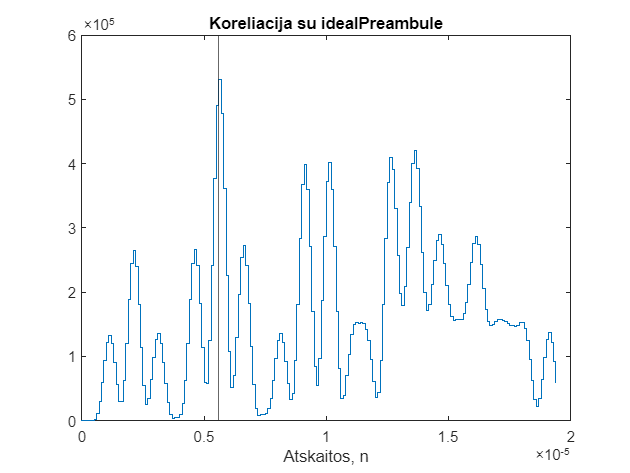


convPreambule = conv(fullSignalADC, preambuleADC);
figure
stairs(t, convPreambule(1:length(fullSignalADC)))
xline(5.6E-6);
title('Koreliacija su idealPreambule')
xlabel('Atskaitos, n')

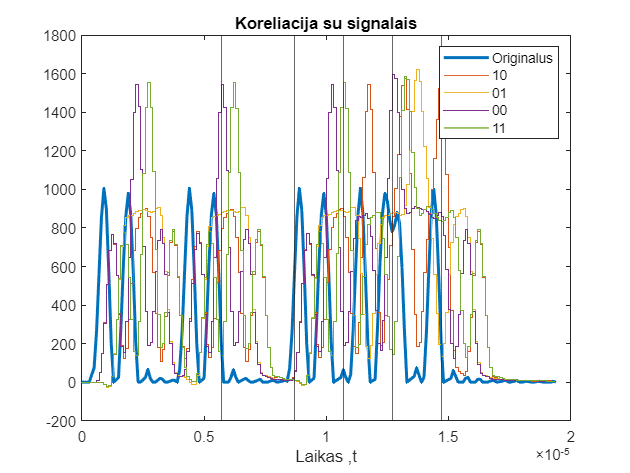



plot(t, fullSignalADC*5, 'LineWidth',2)
hold on
title('Koreliacija su signalais')
xlabel('Laikas ,t')
konvoliucija3 = xcorr(fullSignalADC, onezero);
stairs(t, konvoliucija3(length(fullSignalADC)-length(oneone):length(konvoliucija3)-length(oneone)))

konvoliucija4 = xcorr(fullSignalADC, zeroone);
stairs(t, konvoliucija4(length(fullSignalADC)-length(oneone):length(konvoliucija3)-length(oneone)))

konvoliucija5 = xcorr(fullSignalADC, zerozero);
stairs(t, konvoliucija5(length(fullSignalADC)-length(oneone):length(konvoliucija3)-length(oneone)))

konvoliucija6 = xcorr(fullSignalADC, oneone);
stairs(t, konvoliucija6(length(fullSignalADC)-length(oneone):length(konvoliucija3)-length(oneone)))

xline(5.7E-6);
xline(5.7E-6+3E-6);
xline(5.7E-6+3E-6+2E-6);
xline(5.7E-6+3E-6+4E-6);
xline(5.7E-6+3E-6+6E-6);

%xline(117/fdiskret, 'color','green');
%xline(138/fdiskret, 'color','green');
%xline(159/fdiskret, 'color','green');

legend("Originalus", "10", "01", "00", "11")

hold off

[amplitude, vieta] = max(convPreambule) %

amplitude = 530740

vieta = 57

vietaLaike = vieta / fdiskret %

vietaLaike = 5.7000e-06

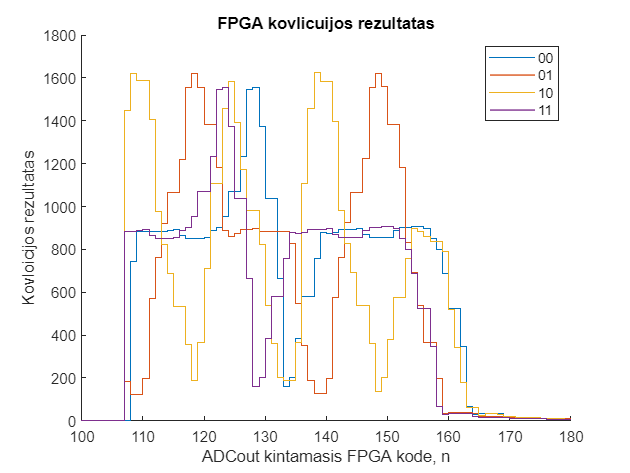

%IMIMAS IS MODELSIMO
msfile = fopen('modelsimData.txt','r');
pliusas = char(43);
formatSpec = ['%d %d %d %d %d %d %d %d'];

msdata = fscanf(msfile,formatSpec, [8 Inf]);

% time +4 arrIndex  adcout 00 01 10 11 %Kaip isrikiuota inforamcija is FPGA

for i = 1:length(msdata(4, :))
    msdata(4, i) = bin2dec(string(msdata(4, i)));
end

figure
%stairs(msdata(4, :)*10, 'LineWidth',2) %ADC verciu iejimas
hold on
stairs(msdata(3, :), msdata(5, :)) %Pagal arrIndex
stairs(msdata(3, :), msdata(6, :))
stairs(msdata(3, :), msdata(7, :))
stairs(msdata(3, :), msdata(8, :))
xlim([100, 180])

title("FPGA kovlicuijos rezultatas")
ylabel("Kovloicijos rezultatas")
xlabel("ADCout kintamasis FPGA kode, n")

legend("00", "01", "10", "11")

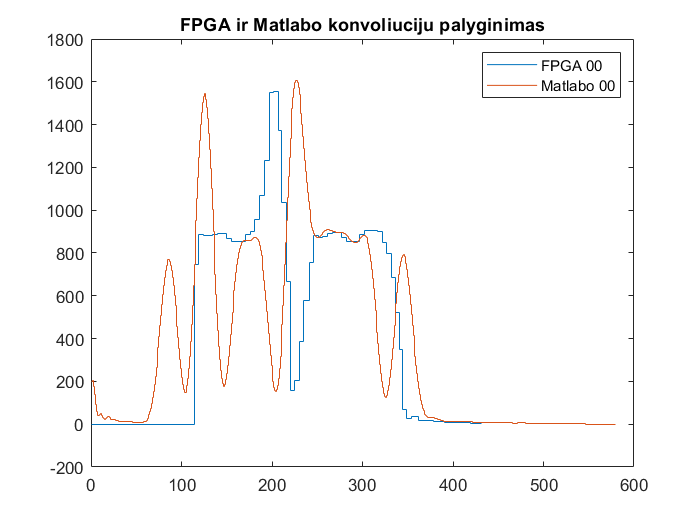


figure
stairs(msdata(5, :))
hold on
stairs(resample(konvoliucija5(245:length(konvoliucija5)), 4, 1))
title("FPGA ir Matlabo konvoliuciju palyginimas")
legend("FPGA 00", "Matlabo 00")
hold off

function y = GenerateConv(a, b)
    y = zeros(1, length(a));
    for i = 1:length(a)-length(b)
        if(i < length(b))
            testArr = [b(1:i), zeros(1, length(a)- i)];
        else
            testArr = [zeros(1, i), b, zeros(1, length(a)-length(b) - i)];
        end
        length(testArr);
        y(i) = sum(a.*testArr);
    end
end

